at first we are going to read the image data

img_data=imread("D:\Downloads\Untitled design.png")

img_data = 788×940×3 uint8 array
img_data(:,:,1) =

   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255

now we have to resize 

[width,height]=size(img_data)

width = 788

height = 2820

now detecting face using object

face_detector=vision.CascadeObjectDetector()

face_detector =   vision.CascadeObjectDetector with properties:

    ClassificationModel: 'FrontalFaceCART'
                MinSize: []
                MaxSize: []
            ScaleFactor: 1.1000
         MergeThreshold: 4
                 UseROI: false


locating the image 

location_face=step(face_detector,img_data)

location_face =    387   100   310   310


detected_face=insertShape(img_data,'rectangle',location_face)

detected_face = 788×940×3 uint8 array
detected_face(:,:,1) =

   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255  

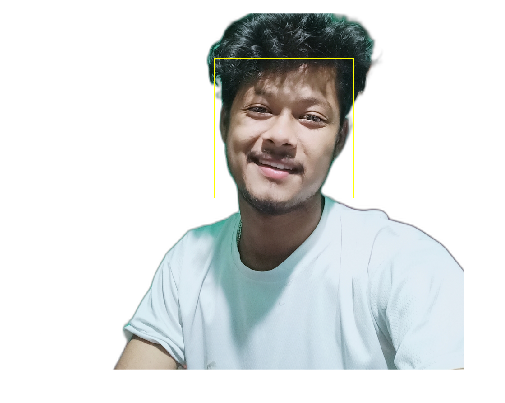

figure;
imshow(detected_face)